Codice a lezione:

n1=[3 5 -6]';
n2=[0 0 1]';

A=[-2 1 0; 1 0 1]';
disp(orth(A));

   -0.9129   -0.0000
    0.3651   -0.4472
   -0.1826   -0.8944



a1=sym([-2 1 0]'); a2=sym([1 0 1]');
v1=a1;
u1=v1/norm(v1);
v2=a2-a2'*u1*u1;
u2=v2/norm(v2);
disp([u1 u2]) %This is the orthonormal basis

$$\left(\begin{array}{cc} -\frac{2\,\sqrt{5}}{5} & \frac{\sqrt{5}\,\sqrt{6}}{30}\\ \frac{\sqrt{5}}{5} & \frac{\sqrt{5}\,\sqrt{6}}{15}\\ 0 & \frac{\sqrt{5}\,\sqrt{6}}{6} \end{array}\right)$$

disp(double([u1 u2]))

   -0.8944    0.1826
    0.4472    0.3651
         0    0.9129



disp(double(orth([a1 a2])))

   -0.8944    0.1826
    0.4472    0.3651
         0    0.9129



disp(orth(A))

   -0.9129   -0.0000
    0.3651   -0.4472
   -0.1826   -0.8944




%Check the same subspace
disp(rank([orth(A) double(([u1 u2])) ]))

     2



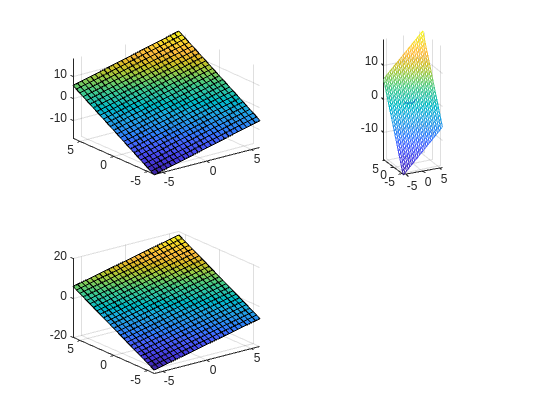


%Visualize what we did until now
clf; figure;
[x,y]=meshgrid(linspace(-6,6,25)); A=[-2 1 0; 1 0 1]';  n1=null(A');

P1=(-n1(1)*x-n1(2)*y)/n1(3); %Cartesian equation of plane
subplot(2,2,1); surf(x,y,P1); axis('tight'); 
subplot(2,2,2); mesh(x,y,P1);
hidden off; hold on; axis equal; 
quiver3([0 0 ],[0 0 ],[0 0], A(1,:), A(2,:), A(3,:),1);
view([n1(1),n1(2),n1(3)]);

%Now let's see the orthonormal basis
A2=[double(u1) double(u2)];
n2=null(A2');
P2=(-n2(1)*x - n2(2)*y)/n2(3);
subplot(2,2,3); surf(x,y,P2);

Codice a lezione 2

dotProd=@(f,g) int(f*g,-1,1);
syms x real; A=sym([-2 1 0; 1 0 1;-1 1 1]')

$$A = \left(\begin{array}{ccc} -2 & 1 & -1\\ 1 & 0 & 1\\ 0 & 1 & 1 \end{array}\right)$$

v=sym('v',[3,1]);
u=sym('u',[3,1]);

v(:,1)=A(:,1);
u(:,1)=v(:,1)/norm(v(:,1));
v(:,2)=A(:,2) - dot(A(:,2),u(:,1))*u(:,1);
u(:,2)=v(:,2)/norm(v(:,2));
v(:,3)=A(:,3) - dot(A(:,3),u(:,1))*u(:,1) - dot(A(:,3),u(:,2))*u(:,2);
u(:,3)=v(:,3)/norm(v(:,3));

disp(u)

$$\left(\begin{array}{ccc} -\frac{2\,\sqrt{5}}{5} & \frac{\sqrt{5}\,\sqrt{6}}{30} & \mathrm{NaN}\\ \frac{\sqrt{5}}{5} & \frac{\sqrt{5}\,\sqrt{6}}{15} & \mathrm{NaN}\\ 0 & \frac{\sqrt{5}\,\sqrt{6}}{6} & \mathrm{NaN} \end{array}\right)$$

disp(v) %The third column is zero

$$\left(\begin{array}{ccc} -2 & \frac{1}{5} & 0\\ 1 & \frac{2}{5} & 0\\ 0 & 1 & 0 \end{array}\right)$$

%Input: N vettori linearmente indipendenti a_i
%Outuput: N vettori ortogonali v_i e n vettori ortonormali u_i

A = sym([-2 1 0; 1 0 1; -1 1 1]')

$$A = \left(\begin{array}{ccc} -2 & 1 & -1\\ 1 & 0 & 1\\ 0 & 1 & 1 \end{array}\right)$$

%A = sym([1 0 0;0 0 0])
r=rank(A)

r = 2


% Inizializzazione dei vettori
n=size(A,1);
m=size(A,2);
v=zeros(n,r);
u=zeros(n,r);

% Passo iniziale
v(:, 1) = A(:, 1)

v =     -2     0
     1     0
     0     0


u(:, 1) = v(:, 1) / sqrt(v(:,1)'*v(:,1))

u =    -0.8944         0
    0.4472         0
         0         0



% Passo intermedio
for k=2:r
    v(:, k) = A(:,k)
    for j=1:k-1
        v(:, k) = v(:, k) - dot(v(:, k), u(:, j)) * u(:, j);
    end
    u(:,k)=v(:,k)/ sqrt(v(:,k)'*v(:,k));
end

v =     -2     1
     1     0
     0     1



disp(v) % Orthogonal vector v

   -2.0000    0.2000
    1.0000    0.4000
         0    1.0000



disp(u) % Orthonormal vector u

   -0.8944    0.1826
    0.4472    0.3651
         0    0.9129



orthA=double(orth(A,'skipnormalization')) %Orthogonal vector v in matlab

orthA =    -2.0000    0.2000
    1.0000    0.4000
         0    1.0000


orthnormA=double(orth(A)) % orthonormal vector u in matlab

orthnormA =    -0.8944    0.1826
    0.4472    0.3651
         0    0.9129


orthnormA'*orthnormA

ans =     1.0000         0
         0    1.0000


u'*u

ans =     1.0000   -0.0000
   -0.0000    1.0000


z=sym([1+7*i 2-6*i])

$$z = \left(\begin{array}{cc} 1+7\,\mathrm{i} & 2-6\,\mathrm{i} \end{array}\right)$$

simplify(norm(z))

$$ans = 3\,\sqrt{10}$$

%z=([1+7*i 2-6*i])
cz=conj(z)

$$cz = \left(\begin{array}{cc} 1-7\,\mathrm{i} & 2+6\,\mathrm{i} \end{array}\right)$$


w=[3 1];
conj(w)

ans =      3     1


sqrt(sum(z.*conj(z)))

$$ans = 3\,\sqrt{10}$$

sqrt(sum(abs(z).*abs(z)))

$$ans = 3\,\sqrt{10}$$

Versione che accetta anche vettori complessi:

%Input: N vettori linearmente indipendenti a_i
%Outuput: N vettori ortogonali v_i e n vettori ortonormali u_i

A = sym([-2+3i 1 0+2i; 1+4i 0 1; -1-6i 1+7i 1]')

$$A = \left(\begin{array}{ccc} -2-3\,\mathrm{i} & 1-4\,\mathrm{i} & -1+6\,\mathrm{i}\\ 1 & 0 & 1-7\,\mathrm{i}\\ -2\,\mathrm{i} & 1 & 1 \end{array}\right)$$

%A = sym([1 0 0;0 0 0])
r=rank(A)

r = 3


% Inizializzazione dei vettori
n=size(A,1);
m=size(A,2);
v=zeros(n,r);
u=zeros(n,r);

% Passo iniziale
v(:, 1) = A(:, 1);

% Passo intermedio
for k=1:r
    v(:, k) = A(:,k);
    for j=1:k-1
        v(:, k) = v(:, k) - dot(u(:, j), v(:, k)) * u(:, j);
    end
    u(:,k)=v(:,k)/ sqrt(sum((conj(v(:,k)).*v(:, k))));
end

v % Orthogonal vector v

v =   -2.0000 - 3.0000i  -0.0556 - 0.8889i  -0.0182 + 0.9636i
   1.0000 + 0.0000i  -0.5556 - 0.7222i   1.0727 - 5.7636i
   0.0000 - 2.0000i  -0.4444 + 1.1111i   3.8727 - 0.8909i


orthA=double(orth(A,'skipnormalization')) %Orthogonal vector v in matlab

orthA =   -2.0000 - 3.0000i  -0.0556 - 0.8889i  -0.0182 + 0.9636i
   1.0000 + 0.0000i  -0.5556 - 0.7222i   1.0727 - 5.7636i
   0.0000 - 2.0000i  -0.4444 + 1.1111i   3.8727 - 0.8909i


u % Orthonormal vector u

u =   -0.4714 - 0.7071i  -0.0318 - 0.5085i  -0.0025 + 0.1348i
   0.2357 + 0.0000i  -0.3178 - 0.4132i   0.1501 - 0.8064i
   0.0000 - 0.4714i  -0.2543 + 0.6356i   0.5418 - 0.1246i


orthnormA=double(orth(A)) % orthonormal vector u in matlab

orthnormA =   -0.4714 - 0.7071i  -0.0318 - 0.5085i  -0.0025 + 0.1348i
   0.2357 + 0.0000i  -0.3178 - 0.4132i   0.1501 - 0.8064i
   0.0000 - 0.4714i  -0.2543 + 0.6356i   0.5418 - 0.1246i


orthnormA'*orthnormA

ans =    1.0000 + 0.0000i   0.0000 - 0.0000i  -0.0000 + 0.0000i
   0.0000 + 0.0000i   1.0000 + 0.0000i   0.0000 - 0.0000i
  -0.0000 + 0.0000i   0.0000 + 0.0000i   1.0000 + 0.0000i


u'*u

ans =    1.0000 + 0.0000i  -0.0000 - 0.0000i   0.0000 + 0.0000i
  -0.0000 + 0.0000i   1.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 - 0.0000i   0.0000 - 0.0000i   1.0000 + 0.0000i


A = sym([-2+3i 1 0+2i; 1+4i 0 1; -1-6i 1+7i 1]')

$$A = \left(\begin{array}{ccc} -2-3\,\mathrm{i} & 1-4\,\mathrm{i} & -1+6\,\mathrm{i}\\ 1 & 0 & 1-7\,\mathrm{i}\\ -2\,\mathrm{i} & 1 & 1 \end{array}\right)$$

v(:, 1) = A(:, 1);
u(:, 1) = v(:, 1) / norm(v(:,1));
j=1

j = 1


uh= u(:,j)'

uh =   -0.4714 + 0.7071i   0.2357 + 0.0000i   0.0000 + 0.4714i


u(:,j)

ans =   -0.4714 - 0.7071i
   0.2357 + 0.0000i
   0.0000 - 0.4714i


y=dot(u(:,j)',v(:,k)) %Dot product

y = 0.5228 - 3.6255i

ym=dot(u(:,j),v(:,k)') %Analogous to conj(y) by one of the main property of the hermitian sesquilinar product

ym = 0.5228 + 3.6255i

x=u(:,j)'*v(:,k) %MATRIX MULTIPLICATION

x = 5.5511e-16 + 8.8818e-16i

v(:,2) = A(:,2) - x*u(:,1);